clc; clear; close all;

% Load Fourier Magnitude Data
F = csvread('fourierMagnitude.txt');

% Define grid size
N = 512; M = 512;

% Define support using your rectangle functions
x = (-N/2:N/2-1);
y = (-M/2:M/2-1);
[X, Y] = meshgrid(x, y);

% Create the support using two rectangle functions
support = rect(X, 111) .* rect(Y, 111);

% Initialize parameters
beta = 0.9;
maxIterations = 1000;
tolerance = 1e-3;

% Initialize complex guess for the diffraction pattern
randomPhase = exp(1i * pi * (rand(N, M) - 0.5));
G_prime = F .* randomPhase;

% Initial guess for the reconstructed image
g = nifft2(G_prime, 1/N, 1/M, N);

% Iterative HIO Algorithm
for iter = 1:maxIterations
    % Compute inverse Fourier transform
    g_prime = nifft2(G_prime, 1/N, 1/M, N);

    % Apply hybrid input-output update rule
    g_new = g_prime;
    g_new(~support) = g(~support) - beta * g_prime(~support);

    % Enforce magnitude constraint
    g = abs(g_new);

    % Fourier transform back
    G = nfft2(g, 1/N, 1/M);

    % Apply modulus constraint
    G_prime = F .* G ./ (abs(G) + 1e-10);

    % Compute error
    error_metric = sqrt(sum(sum((F - abs(G)).^2)) / (N*M));

    % Display progress
    if mod(iter, 50) == 0
        disp(['Iteration ', num2str(iter), ', Error: ', num2str(error_metric)]);
    end

    % Check convergence
    if error_metric <= tolerance
        disp(['Converged after ', num2str(iter), ' iterations with error: ', num2str(error_metric)]);
        break;
    end
end

Iteration 50, Error: 0.06912
Iteration 100, Error: 0.06912
Iteration 150, Error: 0.06912
Iteration 200, Error: 0.06912
Iteration 250, Error: 0.06912
Iteration 300, Error: 0.06912
Iteration 350, Error: 0.06912
Iteration 400, Error: 0.06912
Iteration 450, Error: 0.06912
Iteration 500, Error: 0.06912
Iteration 550, Error: 0.06912
Iteration 600, Error: 0.06912
Iteration 650, Error: 0.06912
Iteration 700, Error: 0.06912
Iteration 750, Error: 0.06912
Iteration 800, Error: 0.06912
Iteration 850, Error: 0.06912
Iteration 900, Error: 0.06912
Iteration 950, Error: 0.06912
Iteration 1000, Error: 0.06912


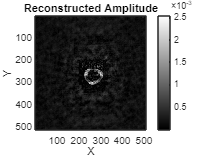


% Display the final reconstructed amplitude
figure;
imagesc(abs(g)); colormap gray; colorbar;
title('Reconstructed Amplitude');
xlabel('X'); ylabel('Y');


%CHATGPT Was used to develop the code
%Questions 
%1. No the algorithm does not reconstruct the way everytime
%because it is iterating, and changing the value of the Fourier transform
%#2. The support is actually the sinc function being plotted at the edges
%of the rectangle function, and is at the zeros.  This could encrypt the
%information somehow I don't know sadly